% Celal AKSOY

# DC Motor System Modeling and Analysing

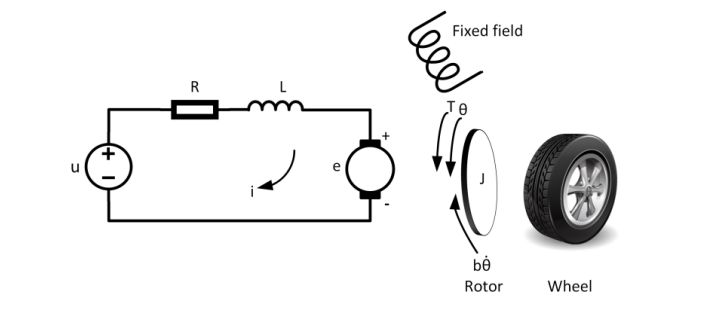

### Transfer Function of Dc Motor System

num = (0.8);
den = [1 12 20.2];
H = tf(num,den)

H =
 
         0.8
  -----------------
  s^2 + 12 s + 20.2
 
Continuous-time transfer function.



#### Step input applying with Matlab's Step Function

To see the system response

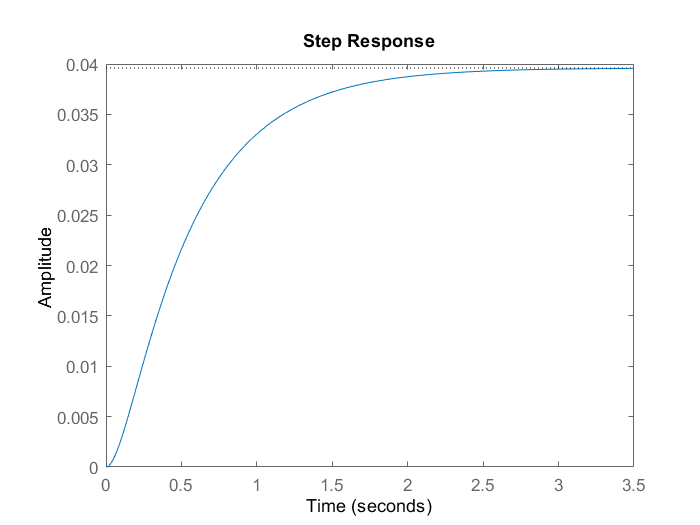

step(H)

### System Analysing with Matlab's Stepinfo Function

To see the system behavior

stepinfo(H)

ans = struct with fields:
        RiseTime: 1.1234
    SettlingTime: 2.0439
     SettlingMin: 0.0357
     SettlingMax: 0.0396
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0396
        PeakTime: 3.8688


##  Analytical Calculation

In order to calculate the desired system data, the step input is applied to the transfer function and transferred to the time domain.

syms s
U = tf(1,[1 0]);
Y = H*U;
num = poly2sym(Y.Numerator,s);
den = poly2sym(Y.Denominator,s);
Yt = ilaplace(num/den)

$$Yt = \frac{4}{101}-\frac{4\,{\mathrm{e}}^{-6\,t}\,\left(\cosh\left(\frac{\sqrt{5}\,\sqrt{79}\,t}{5}\right)+\frac{6\,\sqrt{5}\,\sqrt{79}\,\sinh\left(\frac{\sqrt{5}\,\sqrt{79}\,t}{5}\right)}{79}\right)}{101}$$

## Calculation of System Datas 

### Rise Time (Tr)

The time it takes to get from %10 of steady-state value to %90

syms t
t_01 = vpasolve(Yt==357/100000,t)

$$t\_01 = 0.11773024239157203621482662965812$$

t_09 = vpasolve(Yt==36/1010,t)

$$t\_09 = 1.2490858959246888395332233917771$$

Tr = t_09-t_01

$$Tr = 1.131355653533116803318396762119$$

### Peak Time (Tp)

Peak time is the first time t > 0  when y'(t) = 0. This condition works when omega d times t are equal to 0,pi,2pi....

d_f = diff(Yt)   

$$d\_f = \begin{array}{l} \frac{24\,{\mathrm{e}}^{-6\,t}\,\left(\sigma_{2}+\frac{6\,\sqrt{5}\,\sqrt{79}\,\sigma_{1}}{79}\right)}{101}-\frac{4\,{\mathrm{e}}^{-6\,t}\,\left(6\,\sigma_{2}+\frac{\sqrt{5}\,\sqrt{79}\,\sigma_{1}}{5}\right)}{101}\\ \mathrm{where}\\ \sigma_{1}=\sinh\left(\frac{\sqrt{5}\,\sqrt{79}\,t}{5}\right)\\ \sigma_{2}=\cosh\left(\frac{\sqrt{5}\,\sqrt{79}\,t}{5}\right) \end{array}$$

We took the derivative of the equation, so does the Wd satisfy the condition?

Wn= 4.4744;
Zeta = 1.341;
Wd = Wn*sqrt(1-Zeta^2)

Wd = 0.0000 + 3.9977i

Wd is not real number so this formula won't work. So we can't find peak time

Tp = vpasolve(d_f == 0, t)

$$Tp = 0$$

### Overshoot (Os)

Difference of max value from steady state value

Os=subs(Yt,t,0)-4/101

$$Os = -\frac{4}{101}$$

Peak Time value that we have, it does not reflect the truth. So Overshoot value will also be incorrect.

### Settling Time (Ts)

The value range of the frequency we want

Ts = vpasolve((abs(Yt-4/101))/(4/101)==0.02,t)

$$Ts = 2.0438440677539681930587835159361$$

## System response for different R values

The situation that occurs when the resistance value in the system is reduced has been observed.

for i=0.2:0.1:1
    
num = 0.01 * 0.4 / (0.01 * 0.5);
den = [1 , ((0.05 + 0.01*i)/(0.005)), ((0.01^2 + 0.1*i)/(0.005))];
H2 = tf(num,den);
step(H2);
hold on 
Wn = sqrt((0.01^2 + 0.1*i)/(0.005));
Zeta = ((0.05 + 0.01*i)/(0.005))./(2*Wn);
disp(['R:',num2str(i),'  Wn= ',num2str(Wn),'  Zeta= ',num2str(Zeta)])
end

R:0.2  Wn= 2.005  Zeta= 2.5935


R:0.3  Wn= 2.4536  Zeta= 2.1601


R:0.4  Wn= 2.832  Zeta= 1.9068


R:0.5  Wn= 3.1654  Zeta= 1.7375


R:0.6  Wn= 3.467  Zeta= 1.6152


R:0.7  Wn= 3.7443  Zeta= 1.5223


R:0.8  Wn= 4.0025  Zeta= 1.4491


R:0.9  Wn= 4.245  Zeta= 1.3899


R:1  Wn= 4.4744  Zeta= 1.341


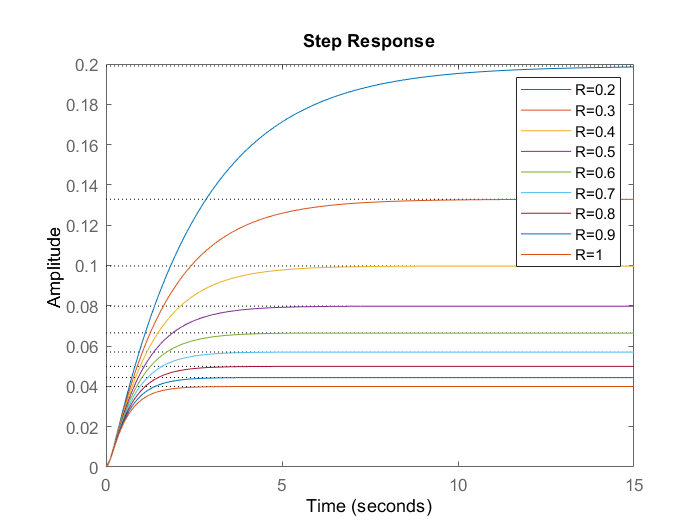

legend('R=0.2','R=0.3','R=0.4','R=0.5','R=0.6','R=0.7','R=0.8','R=0.9','R=1')

## Poles and Zeros

Calculation of poles and zeros in the system with matlab function

z = zero(H)


z =

  0×1 empty double column vector



p = pole(H)

p =    -9.9749
   -2.0251


## Pole-Zero Map

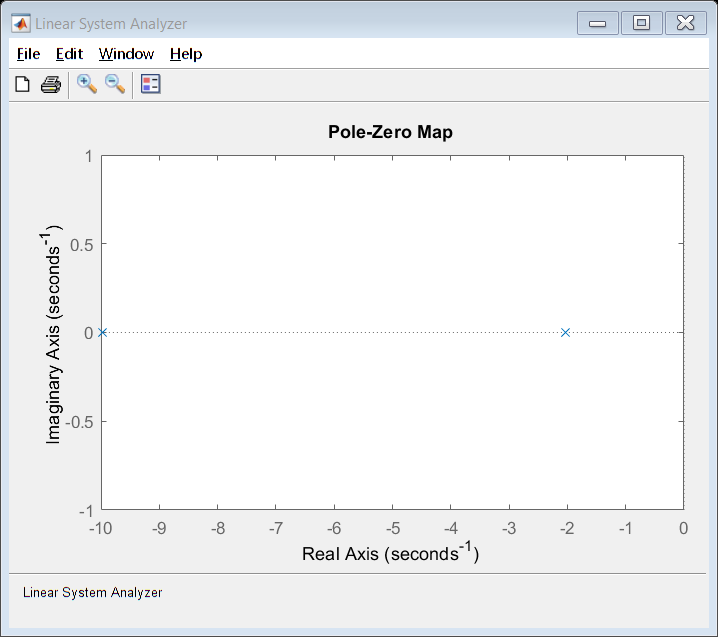

linearSystemAnalyzer('pzmap', H, 0:0.1:5);